# Solution to Burger Equation

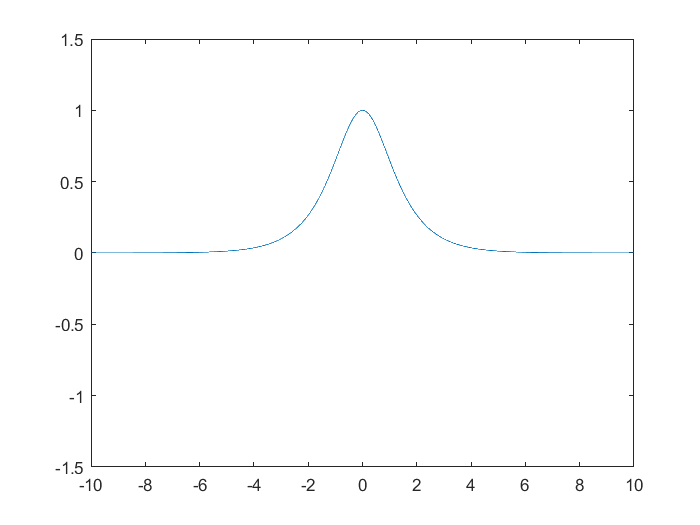

clear;clc;

dx = 0.01;
L = 20;
x = -L/2:dx:L/2-dx;
f = sech(x);
plot(x,f);
axis([-10 10 -1.5 1.5]);

## Solution using ODE45

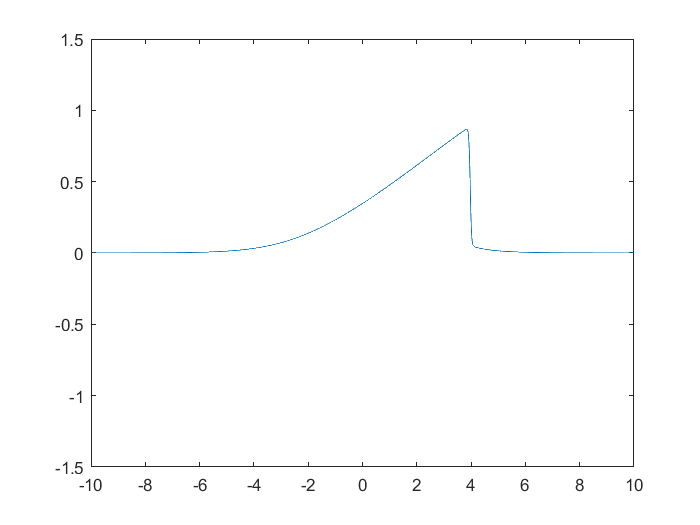

ic = transpose(f);
dt = 0.025;
N = 200;
DATA = zeros(length(ic),N);
for k=1:N
    tk = k*dt;
    [t,u] = ode45(@(t,u) burger_dynamics(t,u,L), [0 dt], ic);
    ic(:) = u(end,:);
    DATA(:,k) = u(end,:);
    plot(x,real(u(end,:)));
    axis([-10 10 -1.5 1.5]);
    drawnow;    
end